data = readtable("Interpolated_All_Averages.csv")

data = 107×13 table
    theta    x6cm_Left_avg    x6cm_Right_avg    x7cm_Left_avg    x7cm_Right_avg    x8cm_Left_avg    x8cm_Right_avg    x9cm_Left_avg    x9cm_Right_avg    x10cm_Left_avg    x19cm_Right_avg    x11cm_Left_avg    x11cm_Right_avg
    _____    _____________    ______________    _____________    ______________    _____________    ______________    _____________    ______________    ______________    _______________    ______________    _______________

    -0.01         1004              1336           2138.4              2692           315

% matlab adds 'x' at start of each column header since they start with
% numbers in the csv file

start = 2; % start point of 'useful' range of measurements
cutoff = 10; % end point of 'useful' range of measurements
theta = data.theta(start:end-cutoff) + pi/6;

l_6 = data.x6cm_Left_avg(start:end-cutoff);
r_6 = data.x6cm_Right_avg(start:end-cutoff);
diff_6 = l_6 - r_6;

l_7 = data.x7cm_Left_avg(start:end-cutoff);
r_7 = data.x7cm_Right_avg(start:end-cutoff);
diff_7 = l_7 - r_7;

l_8 = data.x8cm_Left_avg(start:end-cutoff);
r_8 = data.x8cm_Right_avg(start:end-cutoff);
diff_8 = l_8 - r_8;

l_9 = data.x9cm_Left_avg(start:end-cutoff);
r_9 = data.x9cm_Right_avg(start:end-cutoff);
diff_9 = l_9 - r_9;

l_10 = data.x10cm_Left_avg(start:end-cutoff);
r_10 = data.x19cm_Right_avg(start:end-cutoff); % typo in data csv - should be 10cm
diff_10 = l_10 - r_10;

l_11 = data.x11cm_Left_avg(start:end-cutoff);
r_11 = data.x11cm_Right_avg(start:end-cutoff);
diff_11 = l_11 - r_11;

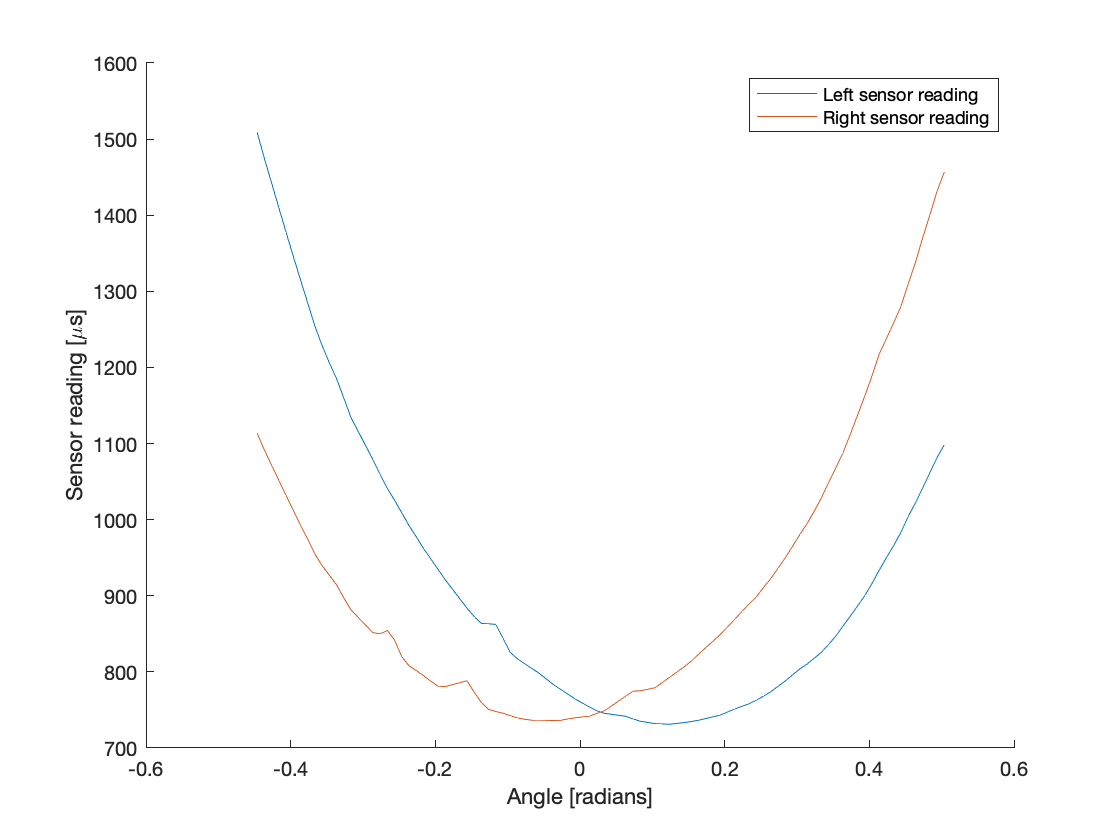

% Sanity check
figure
hold on
plot(theta,l_6)
plot(theta,r_6)
legend('Left sensor reading','Right sensor reading')
ylabel('Sensor reading [\mus]')
xlabel('Angle [radians]')

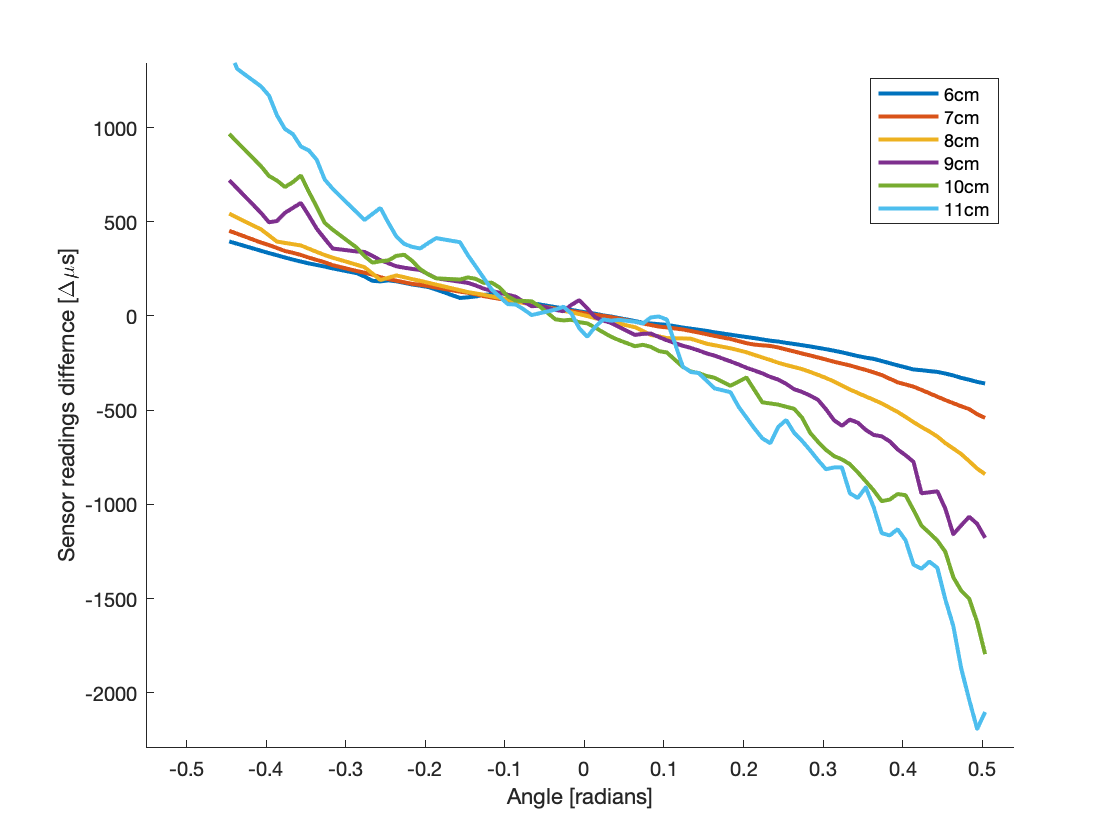

figure
hold on
plot(theta,diff_6,'LineWidth', 2)
plot(theta,diff_7,'LineWidth', 2)
plot(theta,diff_8,'LineWidth', 2)
plot(theta,diff_9,'LineWidth', 2)
plot(theta,diff_10,'LineWidth', 2)
plot(theta,diff_11,'LineWidth', 2)

legend('6cm','7cm','8cm','9cm','10cm','11cm')
ylabel('Sensor readings differnce [\Delta\mus]')
xlabel('Angle [radians]')

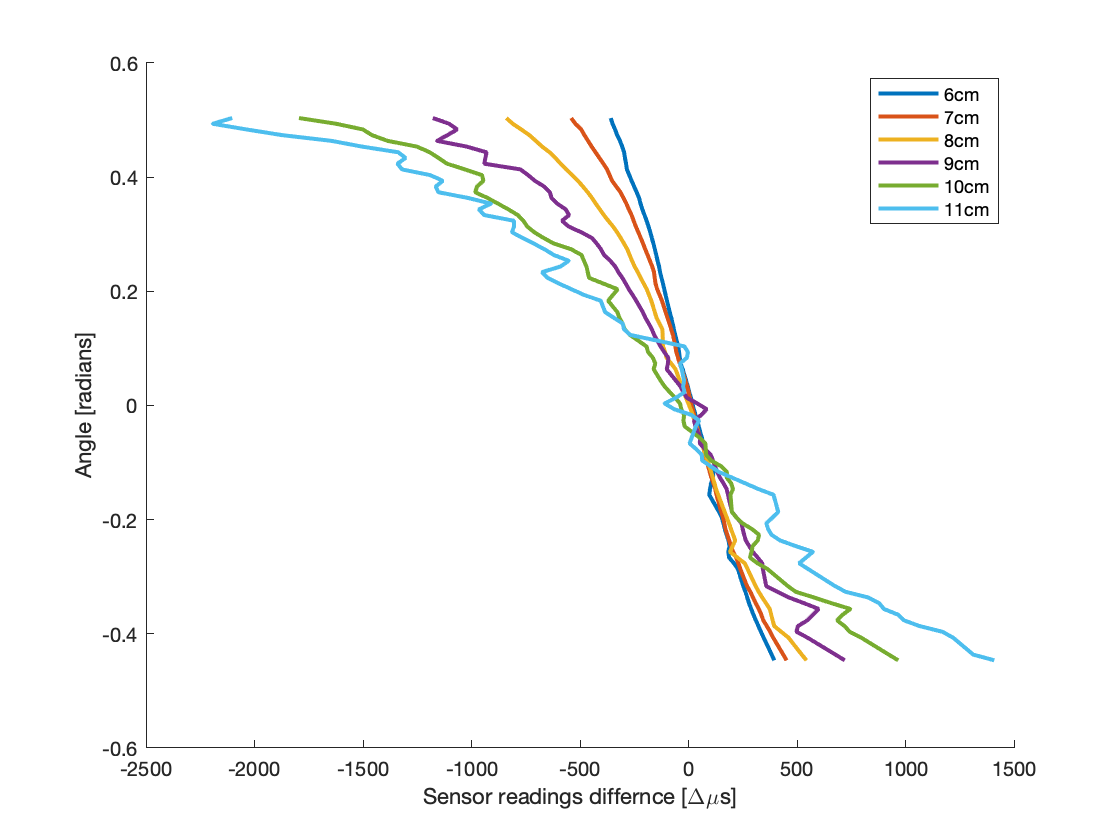

figure
hold on
plot(diff_6,theta,'LineWidth', 2)
plot(diff_7,theta,'LineWidth', 2)
plot(diff_8,theta,'LineWidth', 2)
plot(diff_9,theta,'LineWidth', 2)
plot(diff_10,theta,'LineWidth', 2)
plot(diff_11,theta,'LineWidth', 2)

legend('6cm','7cm','8cm','9cm','10cm','11cm')
xlabel('Sensor readings differnce [\Delta\mus]')
ylabel('Angle [radians]')